**1.    Analyse von Merkmalen, gradientenbasierte Segmentierung (60-90 Min)**

- Zu sehen ist ein Bild mit zu segmentierenden Objekten. Notieren Sie zu jedem Objekt mögliche Merkmale die zur Segmentierung verwendet werden können. Welches sind die aus Ihrer Sicht die jeweils herausstechendsten Merkmale? Begründen Sie. 在你看来，每个案例中最突出的特点是什么？请说明理由。

- Farbe und Form, 

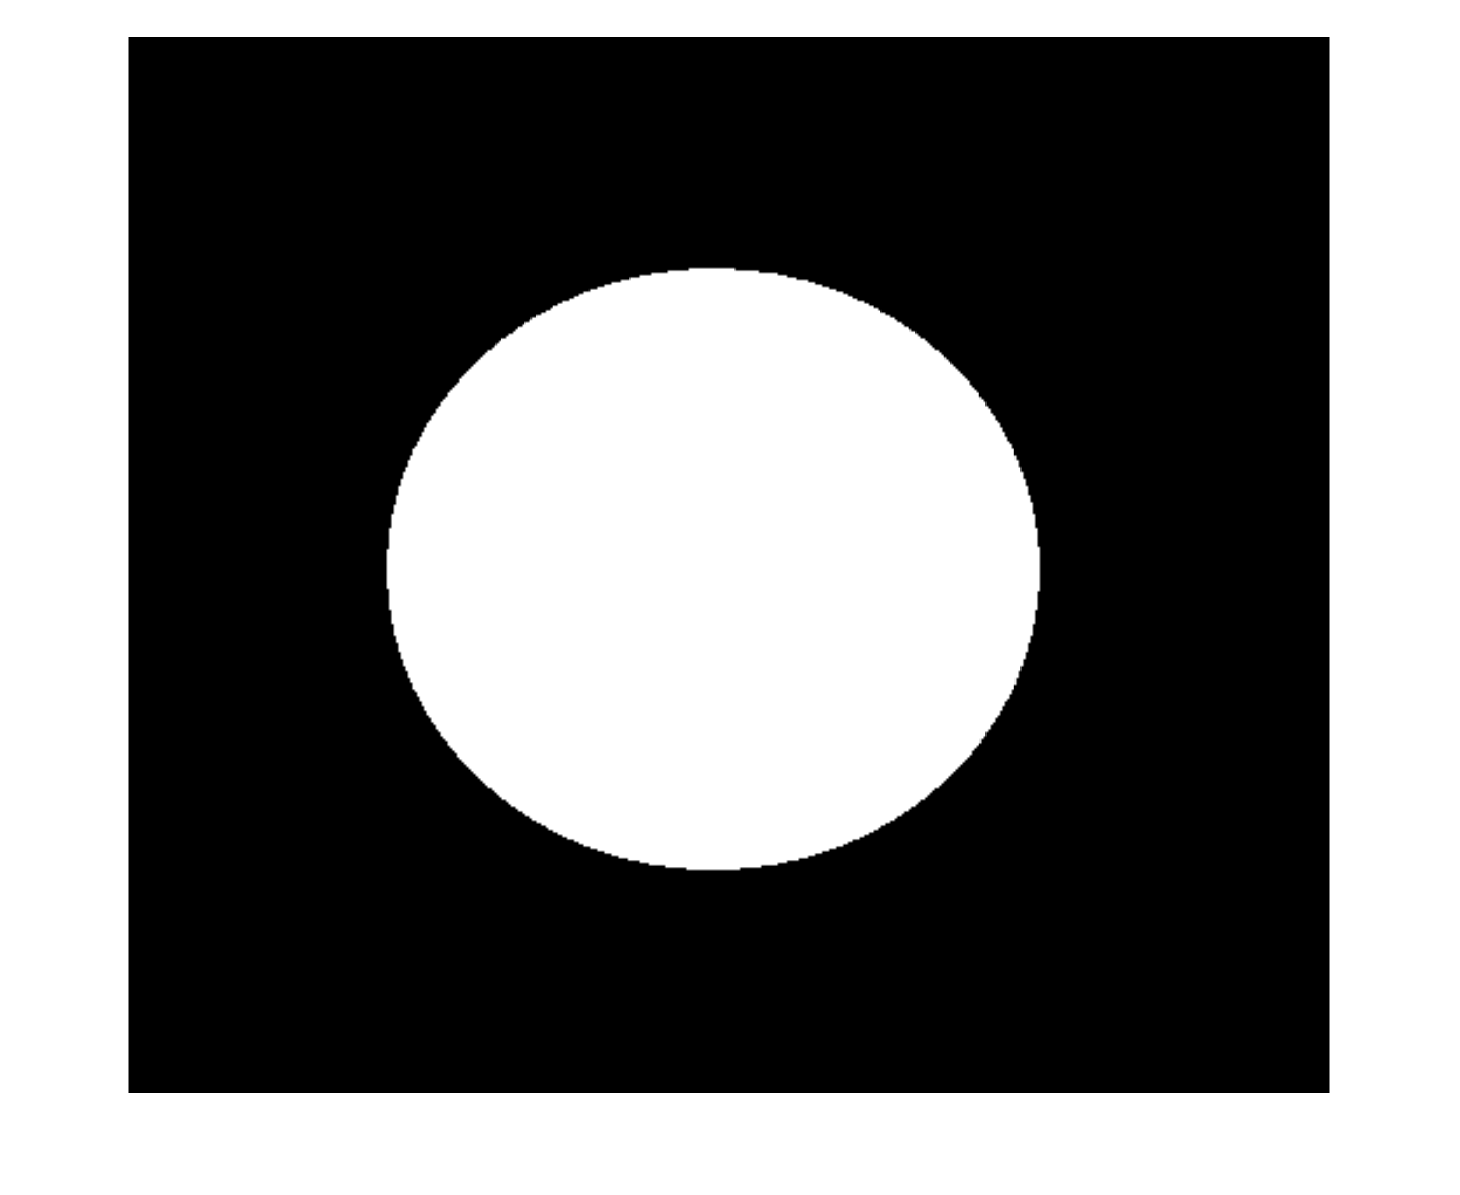

Test = imread("./Test.png");
% fill = imfill(Test,"holes");
BW = im2gray(Test);
imshow(BW)

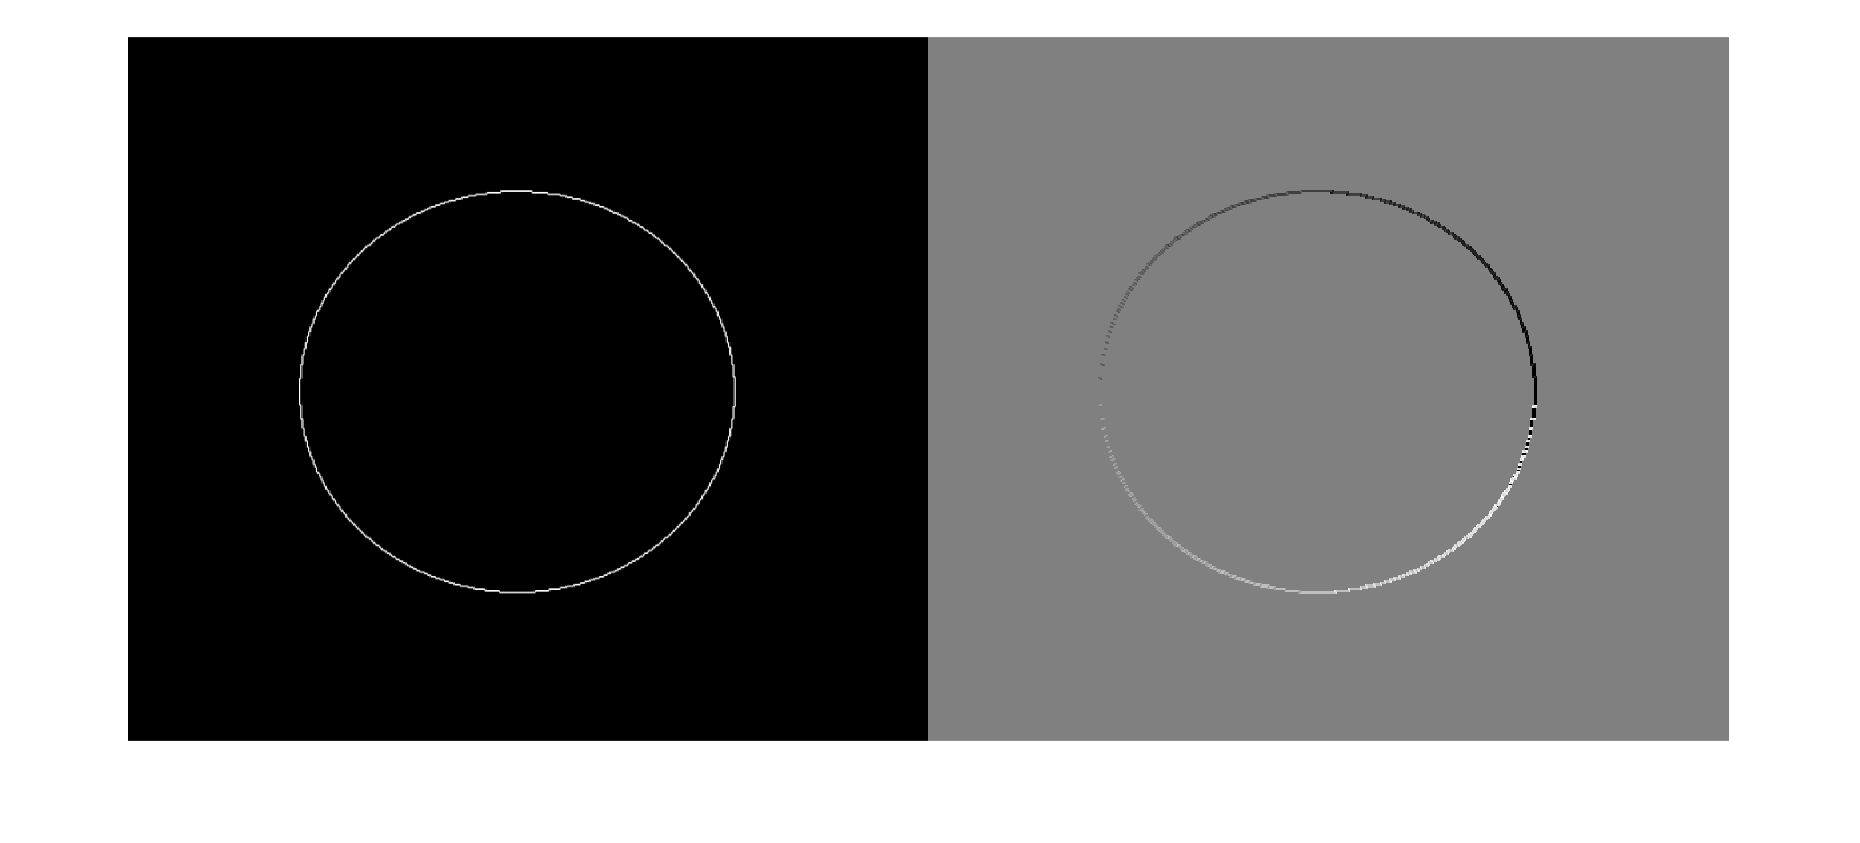

[Gmag, Gdir] = imgradient(BW);
imshowpair(Gmag, Gdir, 'montage');

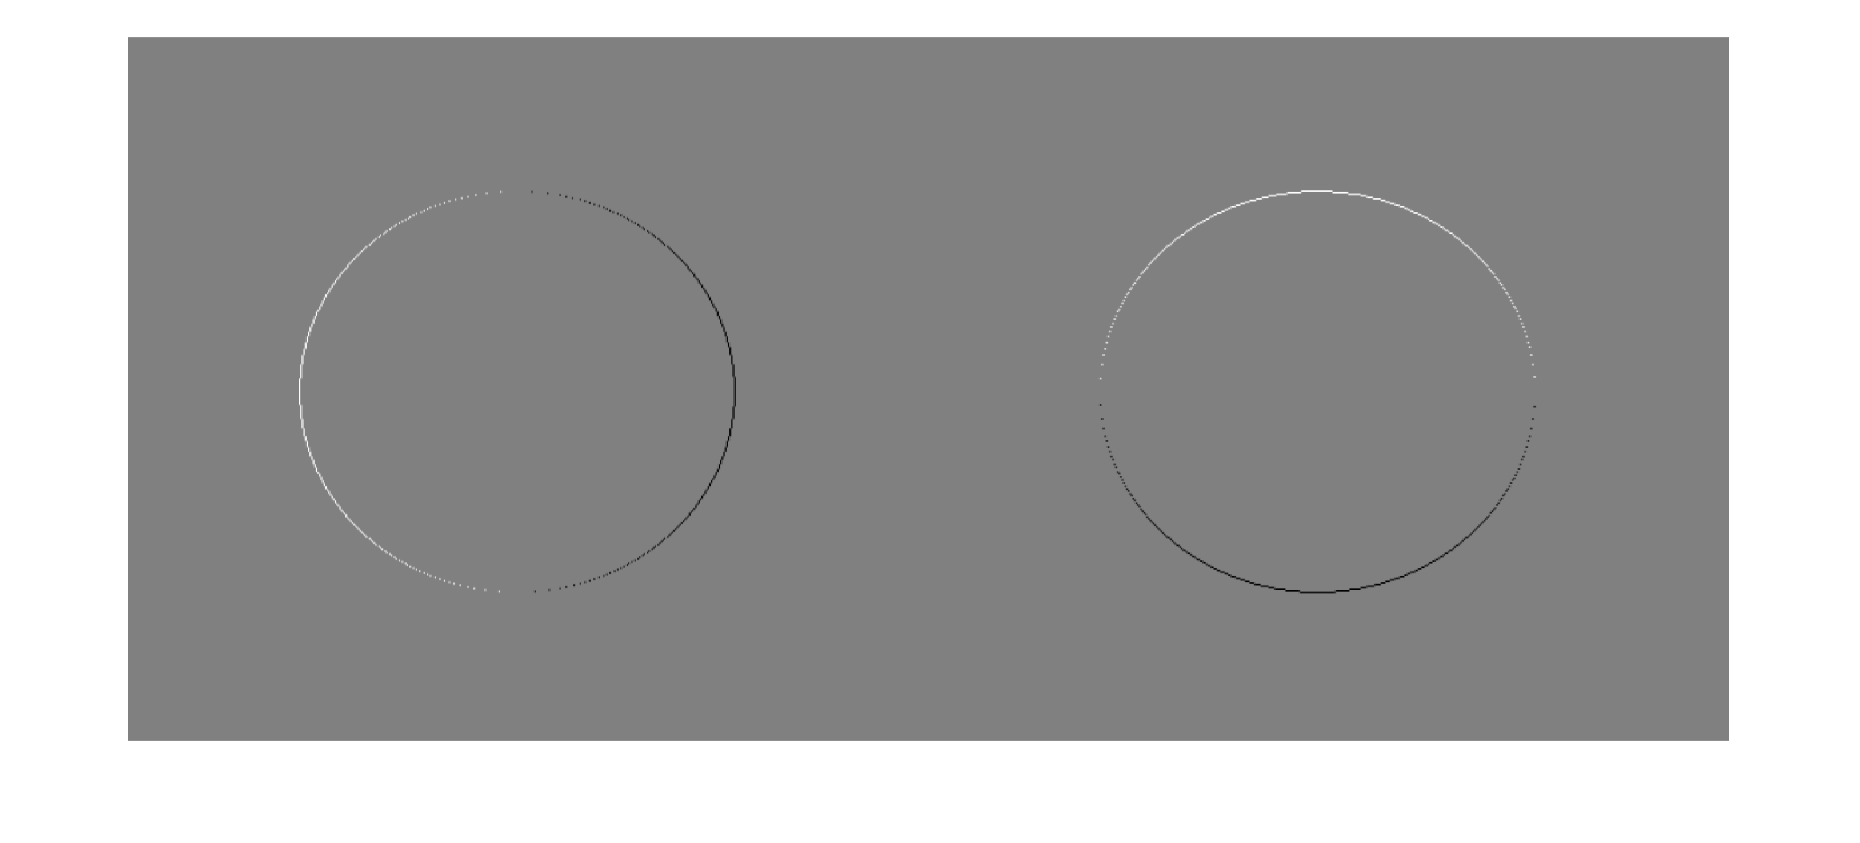

[Gx, Gy] = imgradientxy(BW);
imshowpair(Gx,Gy,'montage'); %点i中的(Gxi,Gyi)向量。

% m=norm([Gx,Gy])
% theta=atan(Gy/Gx); %radians 
% theta=atand(Gy/Gx) %degrees 

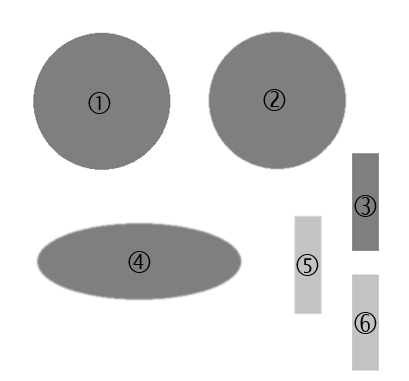

- Erstellen Sie mithilfe der Funktion `imbinarize` ein Script, das eine Segmentierung der Objekte 1 und 3 ermöglicht. Warum ist hier eine Segmentierung allein mit einem Schwellwert nicht möglich? 

- 1 and 3 haben änhlichen Hellihgkeit and Farbe

- Weil 1 und 3 den gleichen Grauwert haben

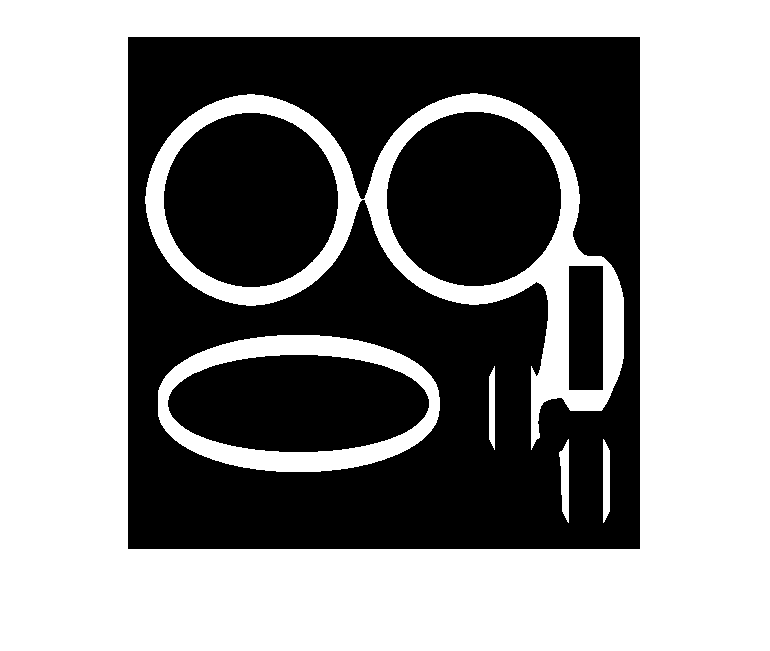

bild_fromen = imread("./Bild_Formen.png");
im_1 = imbinarize(bild_fromen,'adaptive');
imshow(im_1);

filt1 = fspecial('sobel')

filt1 =      1     2     1
     0     0     0
    -1    -2    -1


filt2 = fspecial('prewitt')

filt2 =      1     1     1
     0     0     0
    -1    -1    -1


filt3 = fspecial('gaussian')

filt3 =     0.0113    0.0838    0.0113
    0.0838    0.6193    0.0838
    0.0113    0.0838    0.0113


filt4 = fspecial('laplacian')

filt4 =     0.1667    0.6667    0.1667
    0.6667   -3.3333    0.6667
    0.1667    0.6667    0.1667


filt5 = fspecial('average')

filt5 =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


- Verwenden Sie die Funktion `imgradientxy` zur Berechnung der Richtungsgradienten in X- und Y-Richtung. Stellen Sie die berechneten Bilder nebeneinander dar. Berechnen Sie aus diesen Bildern mit `imgradient` das Betrags- und das Richtungsbild und stellen Sie diese ebenfalls nebeneinander dar.

- 使用imgradientxy函数来计算X和Y方向的方向性梯度。并排显示计算出的图像。从这些带有imgradient的图像中计算出幅度和方向性的图像，并将它们也并排显示。

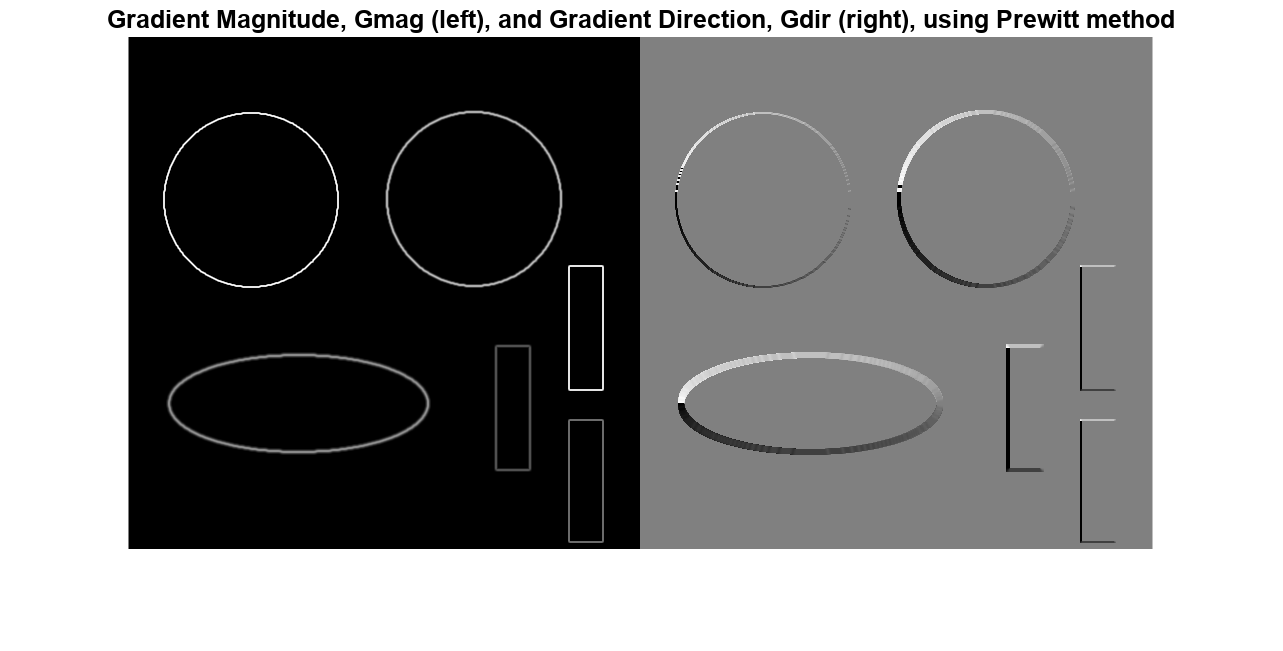

% 返回二维灰度图像或二值图像 I 的梯度幅值 Gmag 和梯度方向 Gdir。
% Die Amplitude des Gradienten in einem Bild beschreibt die Stärke der Änderung der Pixelintensität in einer bestimmten Richtung. Je höher die Amplitude, desto stärker ist die Änderung.
% Die Richtung des Gradienten in einem Bild beschreibt die Richtung, in der die Pixelintensität am stärksten variiert.
[Gmag, Gdir] = imgradient(bild_fromen);
imshowpair(Gmag, Gdir, 'montage');
title('Gradient Magnitude, Gmag (left), and Gradient Direction, Gdir (right), using Prewitt method')

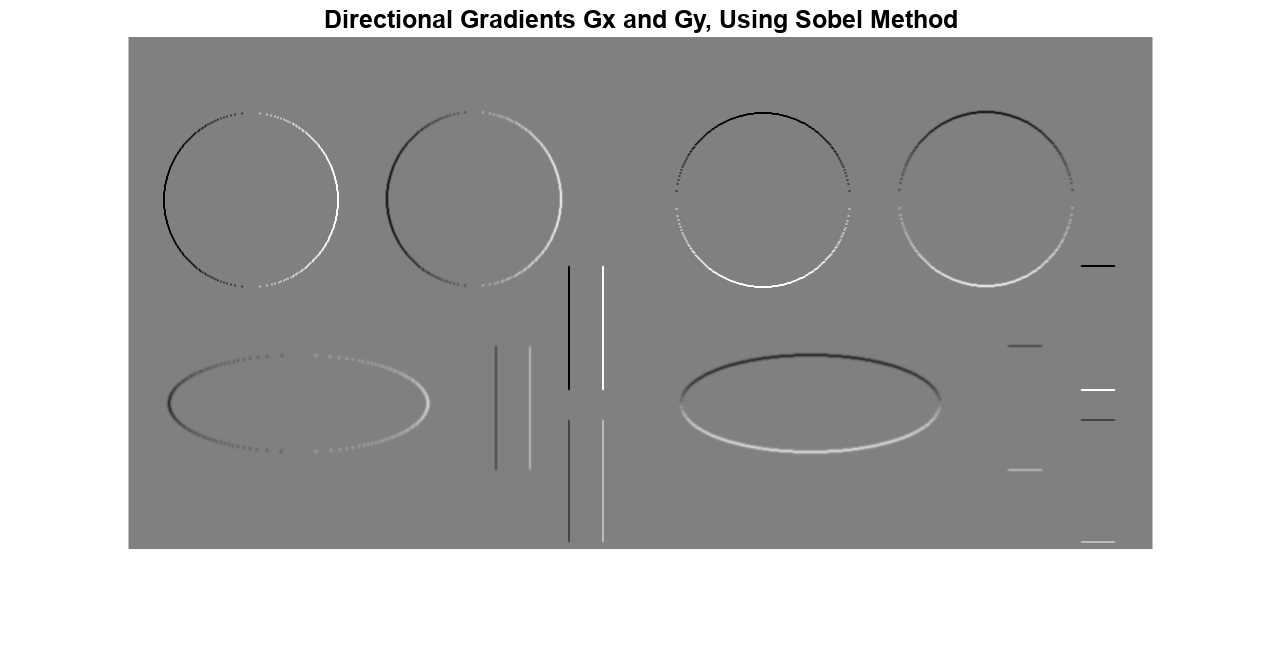

[Gx, Gy] = imgradientxy(bild_fromen);
imshowpair(Gx,Gy,'montage');
title('Directional Gradients Gx and Gy, Using Sobel Method')

% m=norm([Gx,Gy]); 
% theta=atan(Gy/Gx); %radians 
% theta=atand(Gy/Gx); %degrees 
% [Gmag_xy,Gdir_xy] = z(Gx,Gy);
% imshowpair(Gmag_xy,Gdir_xy,'montage')
% title('Gradient Magnitude (Left) and Gradient Direction (Right)')

- Segmentieren Sie anhand des Betragsbildes die Objekte 1 und 3. Stellen Sie es als ausgefüllte Kontur dar (`imfill`*)*

% seg_beitrag = Gmag_xy - Gdir_xy;
% fill = imfill(seg_beitrag,"holes");
% imshowpair(seg_beitrag, fill, 'montage');

- Verwenden Sie jetzt die Funktion `edge`, um die Objekte 1 und 3 zu segmentieren

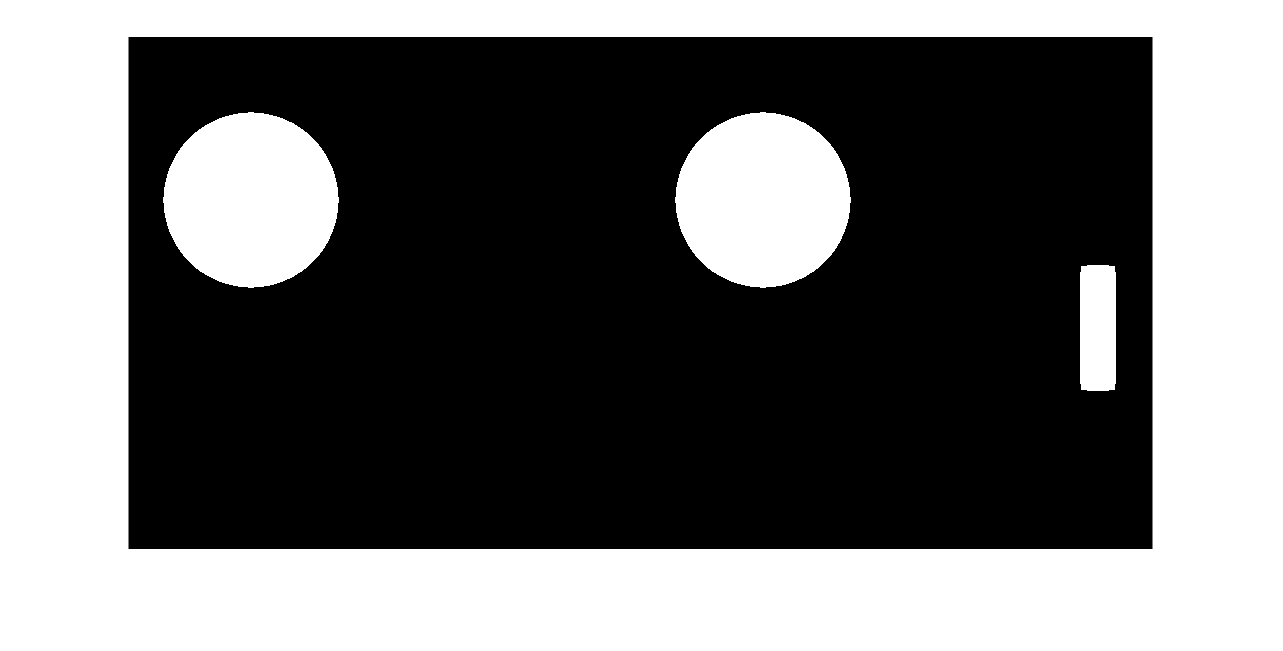

bw_obj_1 = edge(bild_fromen,'canny',0.99);
fill_obj_1 = imfill(bw_obj_1,"holes");
bw_obj_3 = edge(bild_fromen,'canny',0.90);
bw_obj_1_3 = edge(bild_fromen,'canny',0.92);
fill_obj_1_3 = imfill(bw_obj_1_3,"holes");
imshowpair(fill_obj_1,fill_obj_1_3,'montage');

- Erstellen Sie ein Skript, das eine Segmentierung des Objektes 2 ermöglicht.

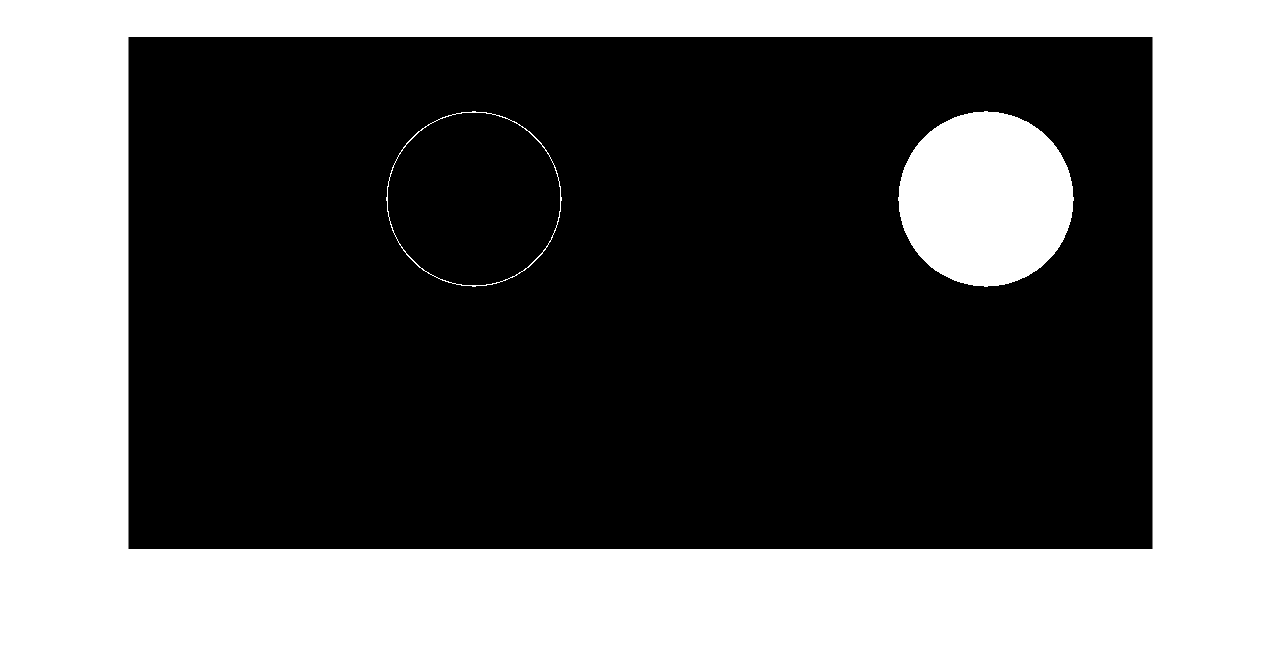

bw_obj_1_2 = edge(bild_fromen,'canny',0.87);
bw_obj_2 = bw_obj_1_2 - bw_obj_1_3;
fill_obj_1_2 = imfill(bw_obj_2,"holes");
imshowpair(bw_obj_2,fill_obj_1_2,'montage');

**2.    Gradientenbasierte Segmentierung des Pumpengehäuses (20-30 Min)**

- Versuchen Sie nun mit Hilfe der neu erlernten Methoden die weiß umrandete Fläche des Pumpengehäuses (Bild1.png) zu segmentieren. 

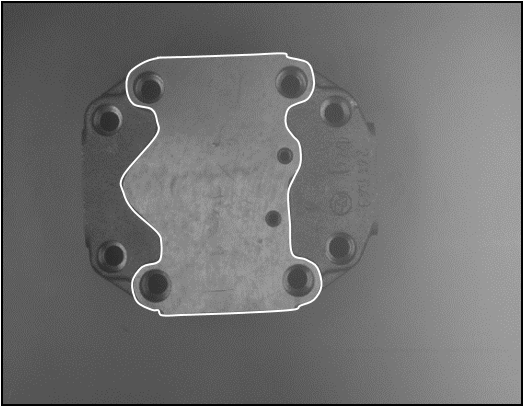

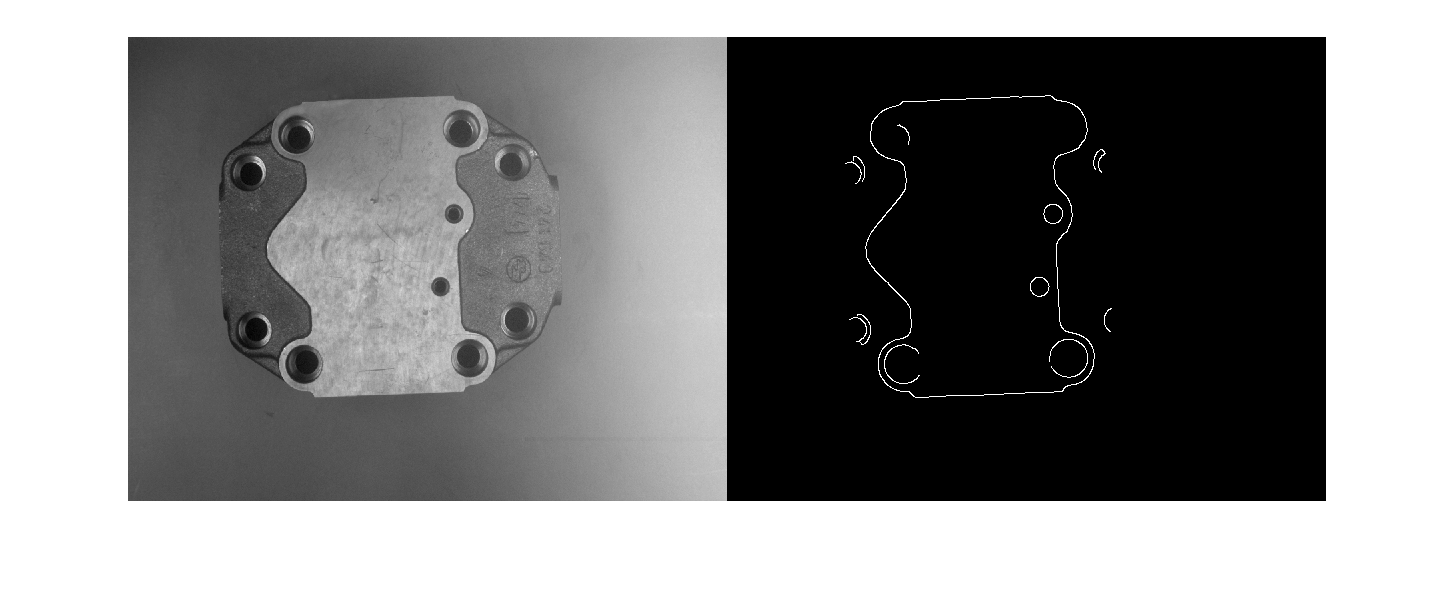

platte = imread('./Bild1.png');
platte_1_2 = edge(platte,'canny',0.55);
imshowpair(platte,platte_1_2,'montage');

- Ist es auch möglich, das Pumpengehäuse vollständig zu markieren? Welche Schwierigkeiten treten auf?

- Testen Sie Ihr Skript auch an dem etwas verschobenen Gehäuse in „Bild3“!

**3.    Vergleich Kantenfilter 1. Ordnung vs. Canny-Algorithmus (30-45 Min)**

- Um ein Gefühl für den Unterschied zwischen einem konventionellen Kantenfilter und dem Canny-Algorithmus zu bekommen, soll ein Script erstellt werden, das beide Operationen miteinander vergleicht. Verwenden Sie dazu die Funktion `edge` und wählen Sie als Methode `Canny` aus*. *Stellen Sie die Bilder mit dem konventionellen Kantenfilter und dem Canny-Algorithmus nebeneinander dar.

- 为了感受一下传统的边缘滤波器和Canny算法的区别，要创建一个脚本，对这两种操作进行比较。要做到这一点，使用边缘函数并选择Canny作为方法。并排显示采用传统边缘滤波器和Canny算法的图像。

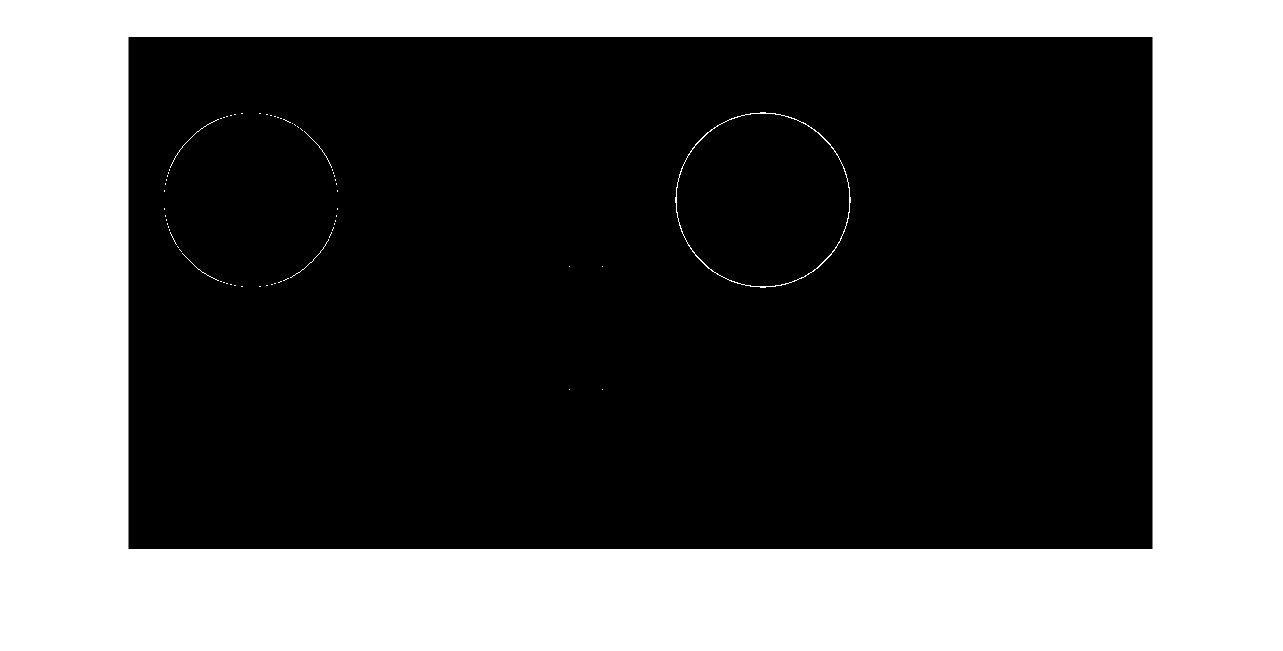

bw_konv = edge(bild_fromen,'sobel',0.26);
bw_canny = edge(bild_fromen,'canny',0.99);
imshowpair(bw_konv,bw_canny,'montage');

- 从下图可以看出，Roberts算子提取边缘的结果边缘较粗，边缘定位不很准确，Sobel算子和Prewitt 算子对边缘的定位就准确了一些，而采用拉普拉斯高斯算子进行边缘提取的结果要明显优于前三种算子，特别是边缘比较完整，位置比较准确。相比而言，Canny 算子提取的边缘最为完整，而且边缘的连续性很好，效果优于以上其他算子，这主要是因为它进行了“**非极大值抑制”和形态学连接操作**的结果。上面几种基于微分的经典边缘提取算子共同的优点是计算简单、速度较快，缺点是**对噪声的干扰都比较敏感**。在实际应用中，由于图像噪声的影响，总要将经典的算法进行改善，结合其他一些算法对一幅含噪声的图像进行处理，然后再采用经典的边缘提取算子提取图像边缘。

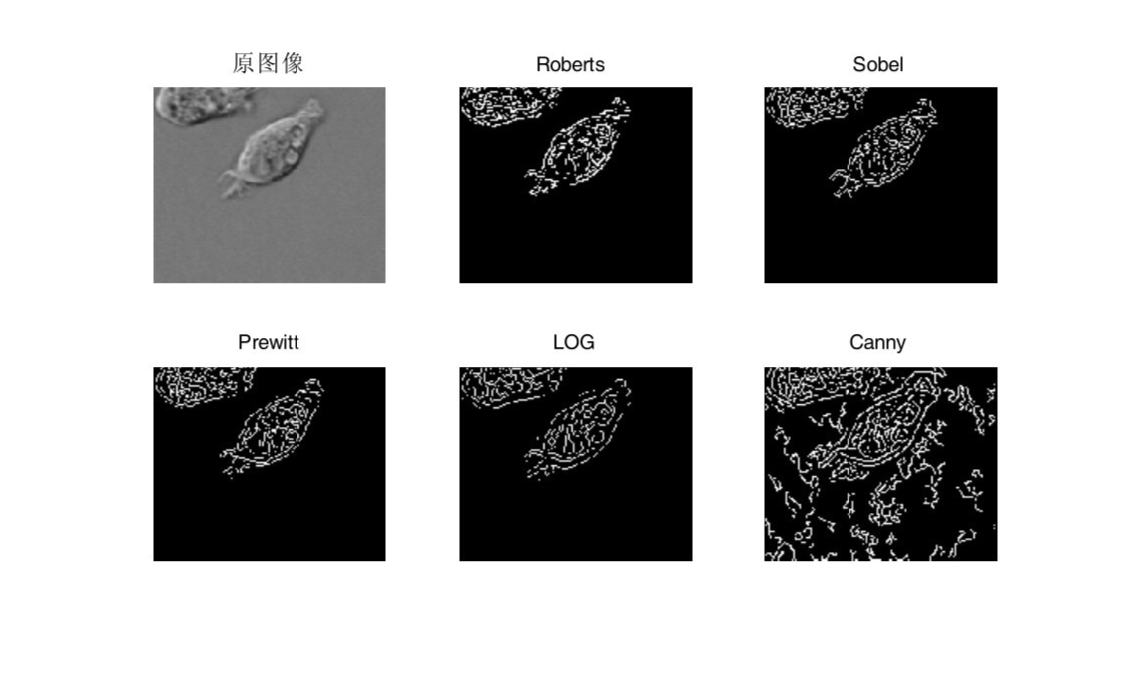

vergleich = imread('./vergleich.png');
imshow(vergleich);

- Wenn Sie das Script nun ausführen, können Sie die beiden Varianten zur Kantendetektion vergleichen. Variieren Sie die Parameter und diskutieren Sie Ihre Beobachtungen. Können Sie die Vorteile des Canny-Algorithmus nachvollziehen?

- 如果你现在运行该脚本，你可以比较两个边缘检测的变体。改变参数并讨论你的观察。你能理解Canny算法的优势吗？

- Schauen Sie sich auch das Bild „Platte1“ an – für dieses Objekt werden wir in der nächsten Übungseinheit eine Geradenerkennung auf der Basis des Kantenbildes durchführen.

- 也请看图像 "Plate1"--对于这个对象，我们将在下一个练习单元中基于边缘图像进行直线检测。